# Tutorial sull'identificazione di modelli ARX non lineari e di Hammerstain-Wiener

load twotankdata.mat

% Questo dataset contiene 3000 sample di input e output che simula un
% sistema a due taniche di questo tipo

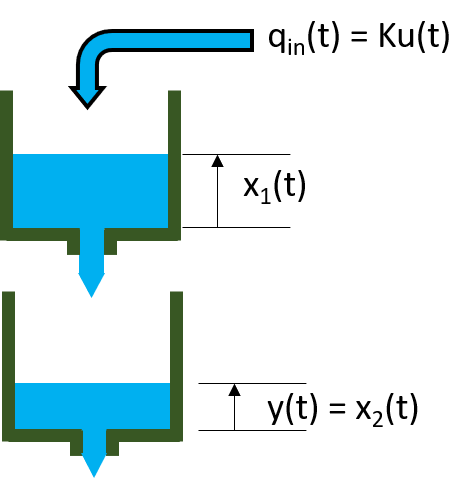

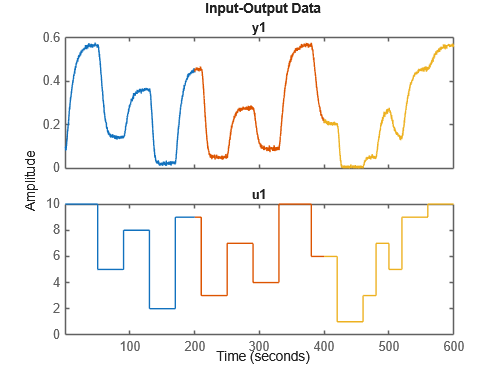

% L'input u(t) [V] rappresenta la tensione applicata alla pompa che riempe la
% prima tanica. 
% L'uscita y(t) [m] rappresenta il livello del liquido della tanica inferiore.

% Il sistema in forma di equazioni di stato è il seguente:
% d/dt x1(t) = 1/A1*(k*u(t) - a1*sqrt(2*g*x1(t)))
% d/dt x2(t) = 1/A2*(a1*sqrt(2*g*x1(t)) - a2*sqrt(2*g*x2(t)))
% y(t) = x2(t)
% Il sistema risulta quindi non lineare rispetto agli stati

% Ai [m^2]: area trasversa della tanica i-esima
% ai [m^2]: area trasversa del foro della i-esima tanica
% g [m/s^2]: forza di gravità
% k: coefficiente di propozionalità tra la tensione di ingresso applicata alla pompa e la
%    quantità di acqua erogata dalla stessa

z=iddata(y,u,0.2);
% spezzo il dataset in 3 subset uguali da 1000 elementi e faccio il grafico
z1 = z(1:1000); % stima (blu)
z2 = z(1001:2000); % validazione 1 (arancione)
z3 = z(2001:3000); % validazione 2 (giallo)
plot(z1,z2,z3)

% L'obiettivo di seguito è quello di stimare l'ordine del modello.
% Solitamente si prova ad utilizzare un modello lineare tipo ARX in modo da
% avere delle informazioni sommarie su quale possa essere l'ordine del
% modello che stiamo studiando
V=arxstruc(z1,z2,struc(1:5,1:5,1:5));
nn=selstruc(V,'aic')

nn =      5     1     3


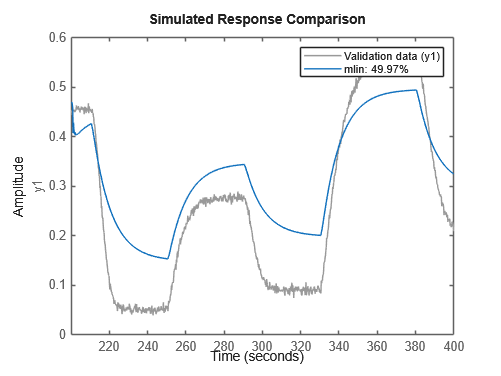

% Risulta che in questo modello ARX, y(t) è stata stimata da 6 regressori
% ovvero y(t-1),y(t-2),...,y(t-5) e u(t-3)
% Proviamo a vedere cosa succede utilizzando un modello lineare su di un
% sistema non lineare
mlin = arx(z1,[5 1 3]);
compare(z2,mlin)

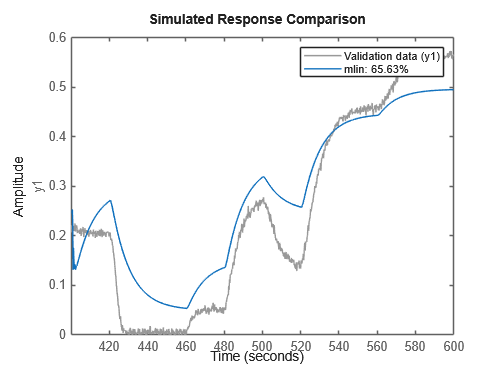

compare(z3,mlin)

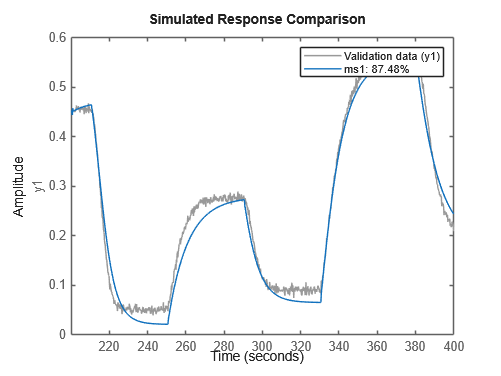

% Vediamo quindi un fit molto basso.
% Utilizzo le informazioni raccolte per stimare un modello ARX non lineare.
% Per creare un modello NARX appropriato, utilizziamo regressori via via
% più complessi.
% Ad esempio possiamo utilizzare la Sigmoid Network che mappa i regressori
% utilizzando una somma di funzioni sigmoidali.
ms1 = nlarx(z1,[5 1 3], idSigmoidNetwork);
% Dopodiché valuto le performance di questa funzione sul dataset z2 
compare(z2, ms1)

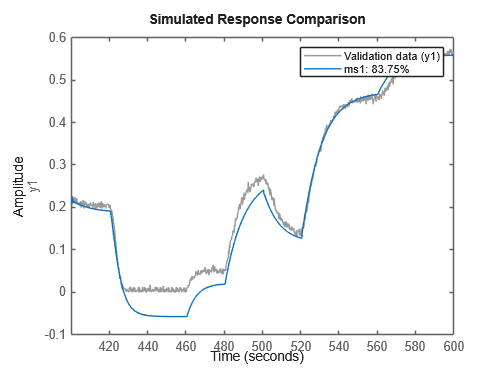

compare(z3, ms1)

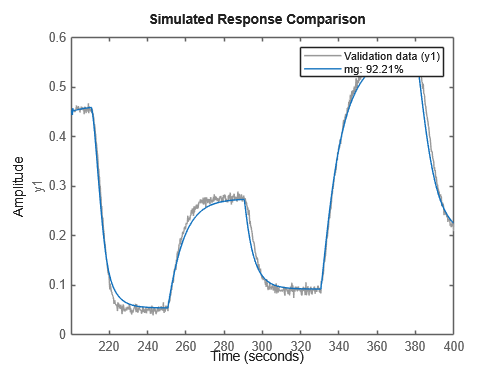

% Utilizziamo come funzione dei regressori la gaussiana.
mg = nlarx(z1, [5 1 3], idGaussianProcess);
compare(z2,mg)

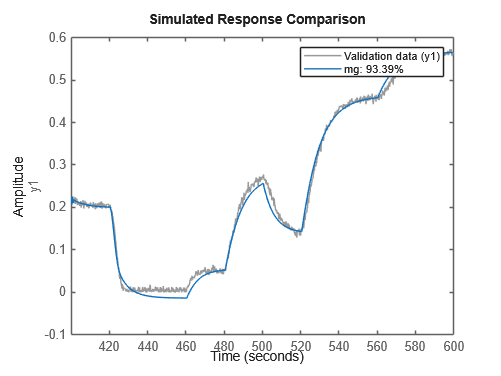

compare(z3,mg)

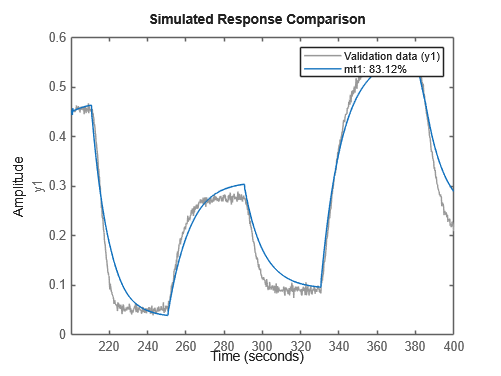

% La funzione idTreePartition è un'altra funzione di mappatura per modelli
% NLARX:
mt1 = nlarx(z1, [5 1 3], idTreePartition);
% Compariamo quindi il modello ottenuto
compare(z2, mt1)

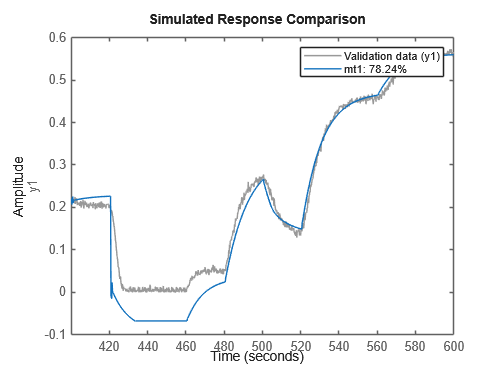

compare(z3, mt1)

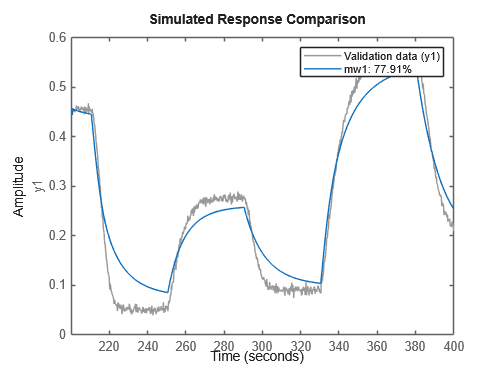

% Utilizzo la funzione non lineare chiamata Wavelet Network che utilizza
% delle combinazioni di wavelet (ondicelle).
mw1 = nlarx(z1,[5 1 3], idWaveletNetwork);
% Vado ad esaminare il risultato ottenuto comparando la risposta del
% modello mw1 ai valori misurati nel dataset
compare(z2,mw1);

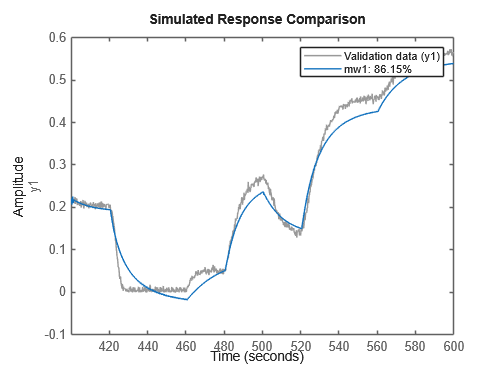

compare(z3,mw1);

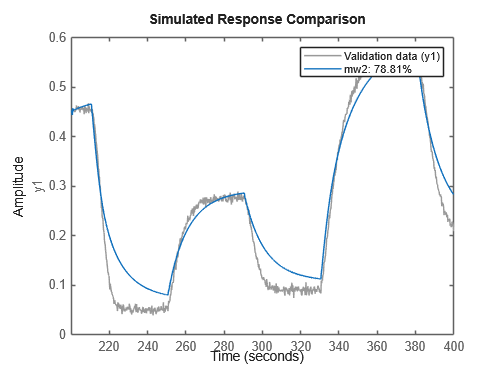

% Poiché mw1 non ha dato risultati abbastanza soddisfacenti ne creo un
% altro in cui vado ad esplicitare il numero di wavelet da utilizzare
mw2 = nlarx(z1,[5 1 3], idWaveletNetwork(5));
% Verifichiamo il fit del modello con i dati di validazione
compare(z2,mw2)

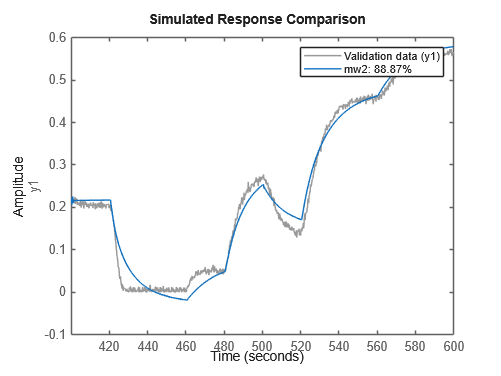

compare(z3,mw2)

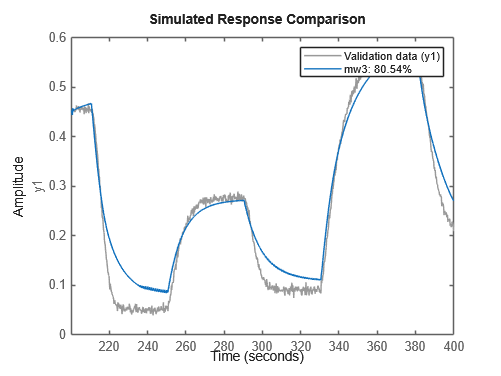

% Proviamo ad aumentare ulteriormente il numero di wavelet
mw3 = nlarx(z1,[5 1 3], idWaveletNetwork(10));
% E mostriamo il fit
compare(z2,mw3)

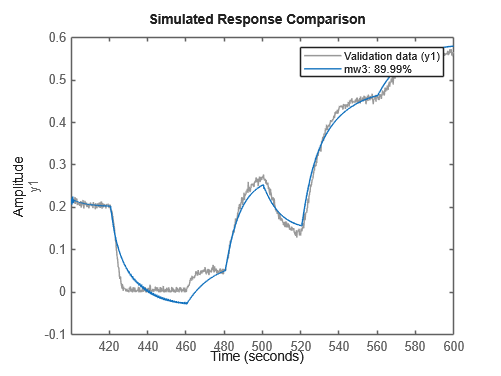

compare(z3,mw3)

% Vediamo quindi che anche cambiando il numero di wavelet il modello
% migliora di pochi punti percentuali.

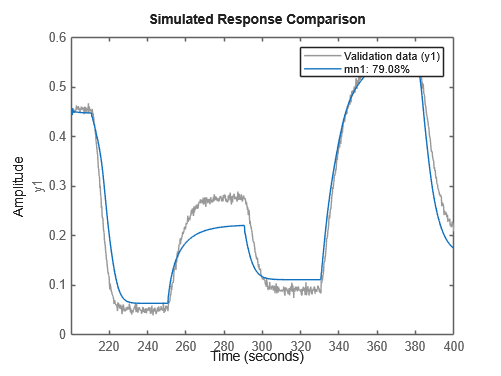

% Utilizzando il toolbox Deep Learning possiamo utilizzare una rete
% neuronale per mappare la funzione del modello non lineare.
ff = feedforwardnet([5 5]); 
%Le funzioni di attivazione del layer 2 vengono settate come RBF
ff.layers{2}.transferFcn = 'radbas'; 
ff.trainParam.epochs = 50;
% Creiamo una funzione per il nostro modello a partire dalla rete creata
OutputFcn = idFeedforwardNetwork(ff);
mn1 = nlarx(z1,[5 1 3], OutputFcn); 
%Compariamo il modello ai dati di validazione
compare(z2, mn1) 

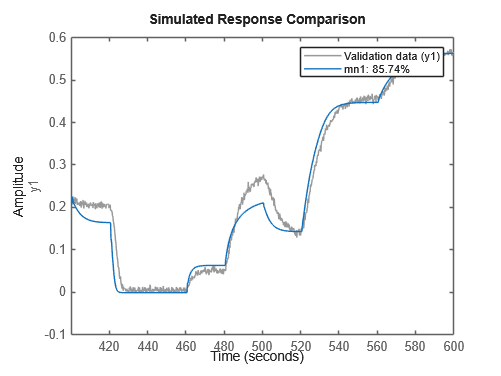

compare(z3, mn1) 

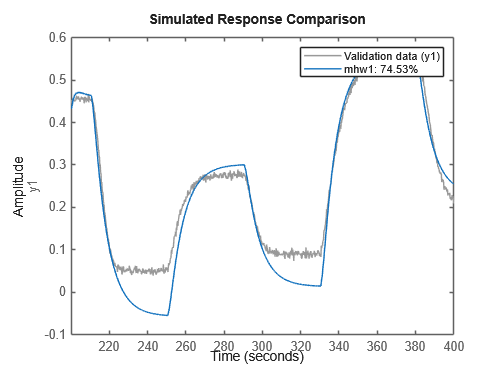

% Vi è la possibilità di utilizzare anche i modelli di Hammerstein-Wiener
% scegliendo l'ordine, il ritardo delle funzioni non lineari di ingresso e
% uscita e anche il tipo di funzioni.
% Utilizziamo funzioni lineari a tratti solo in ingresso
mhw1 = nlhw(z1, [1 5 3], idPiecewiseLinear, []);
% Valutiamo quindi il risultato ottenuto
compare(z2,mhw1)

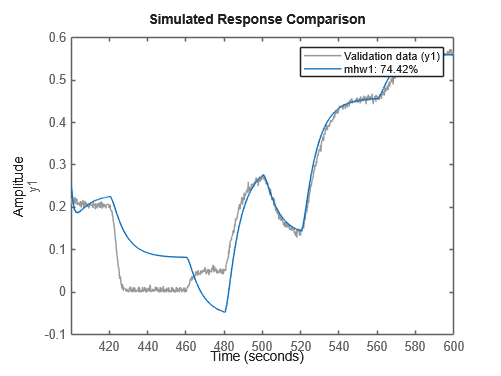

compare(z3,mhw1)

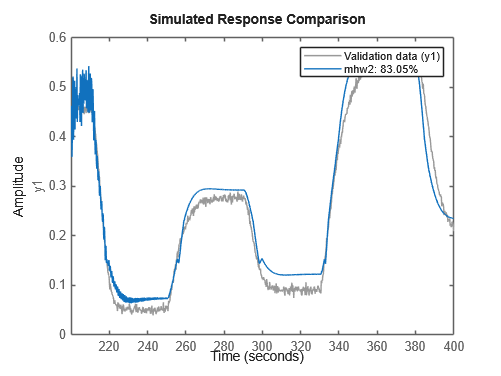

% Utilizziamo funzioni lineari a tratti solo in uscita
mhw2 = nlhw(z1, [1 5 3], [], idPiecewiseLinear);
% Valutiamo quindi il risultato ottenuto
compare(z2,mhw2)

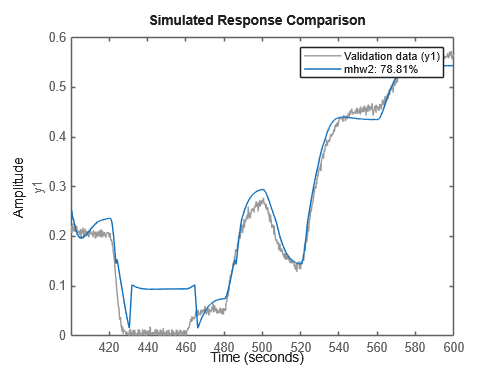

compare(z3,mhw2)

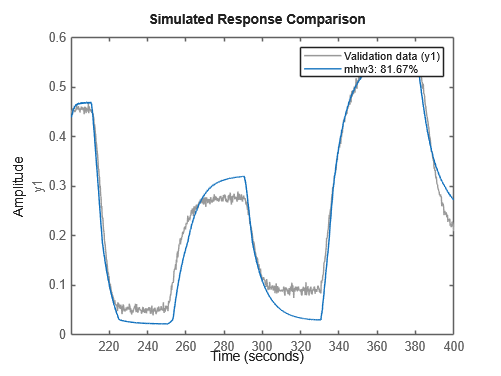

% Utilizziamo funzioni lineari a tratti sia in ingresso che in uscita
mhw3 = nlhw(z1, [1 5 3], idPiecewiseLinear, idPiecewiseLinear);
% Valutiamo quindi il risultato ottenuto
compare(z2,mhw3)

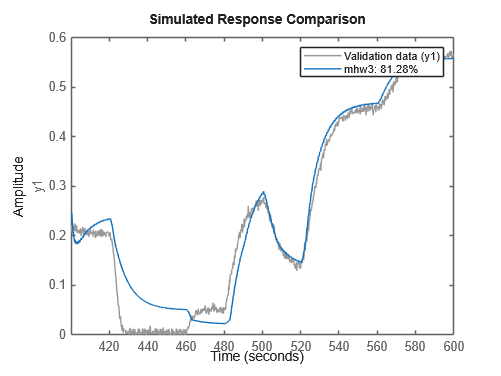

compare(z3,mhw3)